# tRGS 

In this notebook, we are implementing tensor randomized Gauss Seidel for solving A*X =B.

addpath('tproduct toolbox 2.0 (transform)/')

First, we'll generate a consistent overdetermined tensor linear systems.

l = 20;
p = 10;
n = 30;
m = 40;

%generate tensors
A = randn(m,l,n);
X_true = randn(l,p,n);

%generate consistent measurements
B = tprod(A,X_true);

%generate equivalent matrix system
[matA,matB,matX_true] = matricization(A,B,X_true);

Now, let's test the implementation of tRGS.

%run some iterations of tRGS
num_its = 10000;
errs = tRGS_err(A,B,zeros(l,p,n),num_its,X_true)

errs =    77.1163   76.1750   75.0116   73.8717   72.4842   72.4842   72.4544   71.1576   71.1184   69.8387   68.5535   67.1378   65.5329   65.5329   65.2359   63.4300   63.4300   63.4300   63.1110   62.9646   61.1921   61.1220   58.9931   57.2478   56.7551   56.5488   56.5488   56.5368   56.3843   56.2105   54.2445   54.1980   52.0040   51.5829   51.1842   50.8630   50.7390   50.6724   50.6580   50.5388   48.1483   48.1149   45.4832   45.1512   44.8514   42.1529   38.7637   38.3232   37.6369   37.3125


X_ln = tprod(tpinv(A),B);

%run some iterations of RGS
mat_err = tRGS_err(matA,matB,zeros(n*l,p,1),num_its, matX_true);
matX_ln = tprod(tpinv(matA),matB);


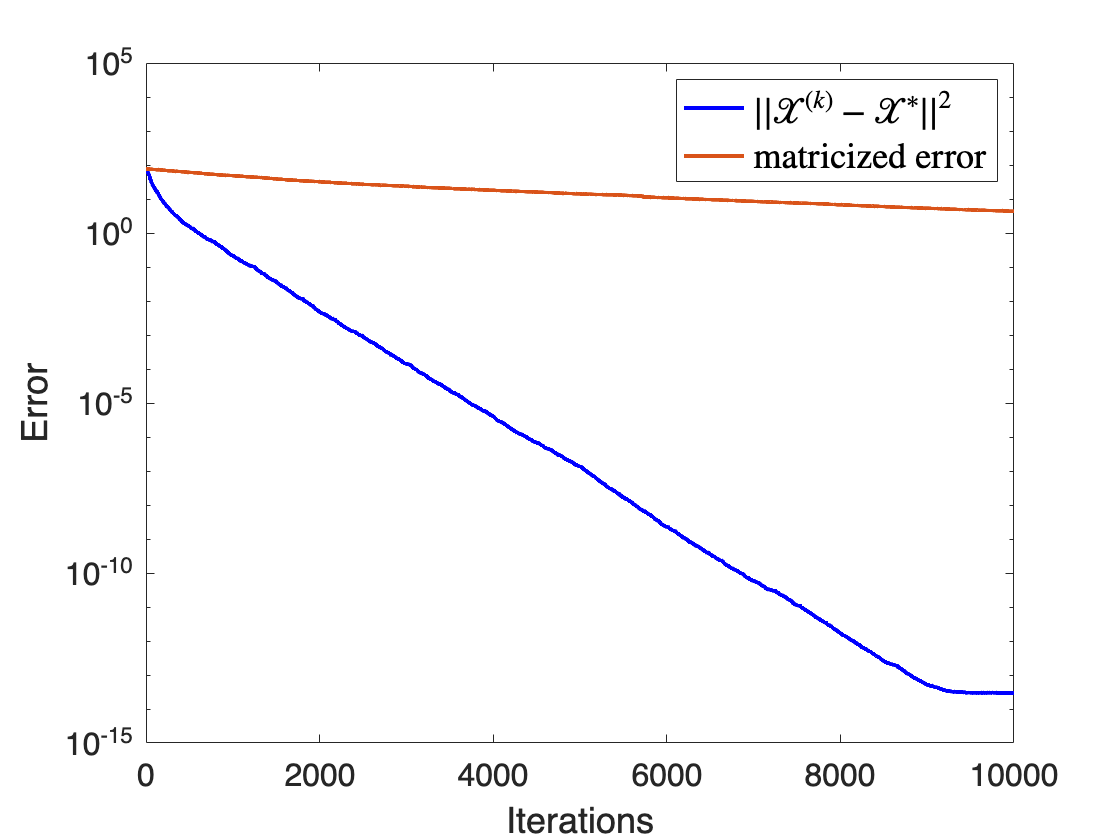

%plot errors vs iterations
figure(1);
semilogy(0:num_its,errs,'b-',0:num_its,mat_err,'LineWidth',2)
hold on
set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','matricized error','Interpreter','latex','FontSize',18)
saveas(gca,'fig3.png')
hold off

l = 20;
p = 10;
n = 30;
m = 30;

%generate tensors
A = randn(m,l,n);
X_true = randn(l,p,n);

%generate consistent measurements
B = tprod(A,X_true);

%generate equivalent matrix system
[matA,matB,matX_true] = matricization(A,B,X_true);

Now, let's test the implementation of tRGS.

%run some iterations of tRGS
num_its = 10000;
errs = tRGS_err(A,B,zeros(l,p,n),num_its,X_true)

errs =    77.5982   76.8960   76.2278   75.3350   74.3425   73.0252   71.9474   70.6352   69.4758   69.2278   69.1289   68.9458   67.7848   67.6785   67.6701   65.9109   64.3693   62.7075   62.7373   62.8110   61.0576   60.8032   60.6858   60.5463   60.5459   59.2615   59.2446   59.1820   58.9347   58.9135   58.9014   57.0639   57.0639   56.7100   56.7000   54.5206   53.7425   53.7425   53.2146   53.1999   53.1972   53.0507   52.9799   52.8667   52.7401   50.6329   50.6329   50.5317   50.4308   50.2413


X_ln = tprod(tpinv(A),B);

%run some iterations of RGS
mat_err = tRGS_err(matA,matB,zeros(n*l,p,1),num_its, matX_true);
matX_ln = tprod(tpinv(matA),matB);


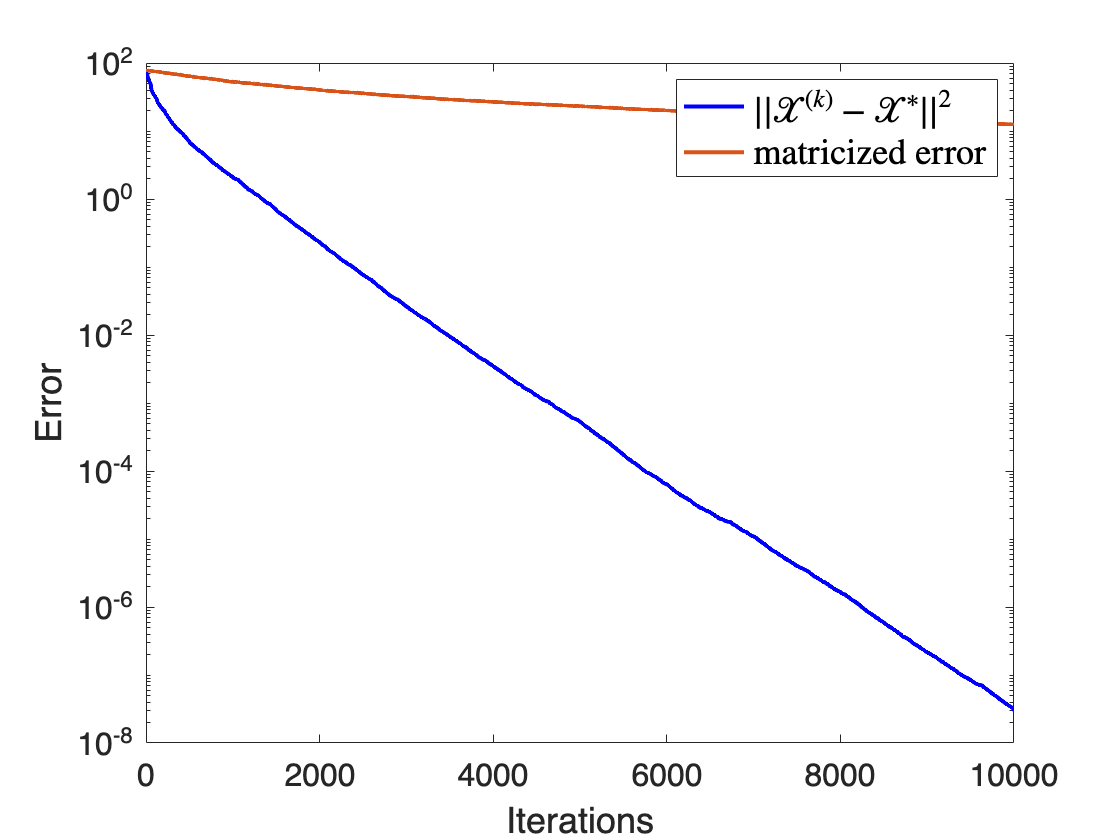

%plot errors vs iterations
figure(2);
semilogy(0:num_its,errs,'b-',0:num_its,mat_err,'LineWidth',2)
hold on
set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','matricized error','Interpreter','latex','FontSize',18)
saveas(gca,'fig4.png')
hold off

l = 20;
p = 10;
n = 30;
m = 20;

%generate tensors
A = randn(m,l,n);
X_true = randn(l,p,n);

%generate consistent measurements
B = tprod(A,X_true);

%generate equivalent matrix system
[matA,matB,matX_true] = matricization(A,B,X_true);

Now, let's test the implementation of tRGS.

%run some iterations of tRGS
num_its = 10000;
errs = tRGS_err(A,B,zeros(l,p,n),num_its,X_true)

errs =    78.9965   79.1740   78.7012   78.3232   77.5030   76.7940   76.2129   75.1938   74.2984   74.2066   74.2556   74.2534   73.0627   71.9735   71.7684   70.8549   70.7787   69.5706   69.4706   69.5835   69.4852   68.2688   67.1768   66.1557   64.8925   64.8925   64.7781   64.1474   63.9952   63.3083   63.2538   63.2319   61.5109   61.4081   61.3882   60.0556   59.6737   59.3994   59.2800   58.7349   58.7349   58.5673   57.3933   57.2369   56.9969   56.7761   56.6830   56.6417   56.5717   56.5313


X_ln = tprod(tpinv(A),B);

%run some iterations of RGS
mat_err = tRGS_err(matA,matB,zeros(n*l,p,1),num_its, matX_true);
matX_ln = tprod(tpinv(matA),matB);


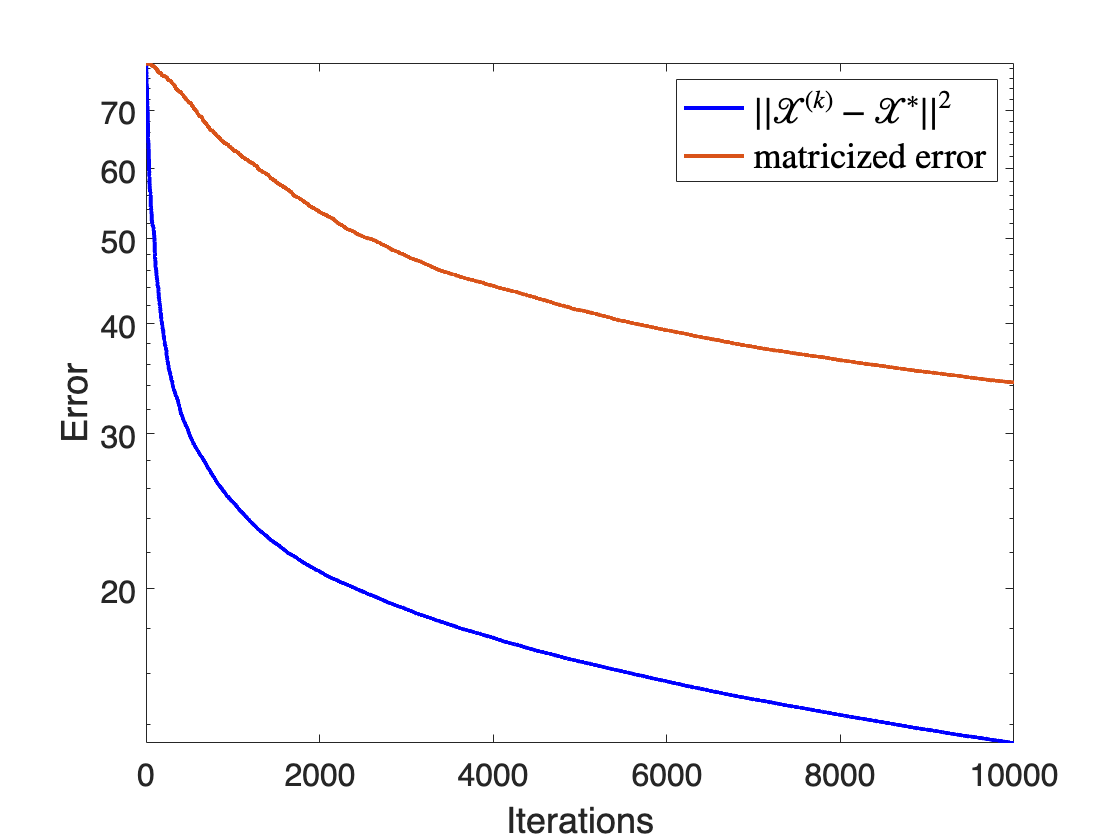

%plot errors vs iterations
figure(3);
semilogy(0:num_its,errs,'b-',0:num_its,mat_err,'LineWidth',2)
hold on
set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$','matricized error','Interpreter','latex','FontSize',18)
saveas(gca,'fig5.png')
hold off

Now, we shall consider the underdetermined setting:

l = 20;
p = 10;
n = 30;
m = 15;

%generate tensors
A = randn(m,l,n);
X_true = randn(l,p,n);

%generate consistent measurements
B = tprod(A,X_true);

%generate equivalent matrix system
[matA,matB,matX_true] = matricization(A,B,X_true);

Now, let's test the implementation of tRGS.

%run some iterations of tRGS
num_its = 10000;
X_ln = tprod(tpinv(A),B);
errs = tRGS_err(A,B,zeros(l,p,n),num_its,X_ln)

errs =    67.3057   68.2487   68.1917   68.3936   67.8278   67.4338   67.4374   66.8105   66.9432   66.9413   66.3469   65.8968   65.7950   64.9949   64.9643   65.0295   65.0295   65.0601   65.0835   65.1347   64.4007   64.3800   63.8800   63.9287   63.1399   63.2129   62.0507   61.9778   62.2972   61.3901   61.3701   60.2695   59.7418   59.6730   59.6730   59.5131   59.4154   59.3577   59.4031   58.4181   58.3940   58.3888   58.1729   58.0972   58.0632   57.9611   57.9498   57.9408   57.9870   57.9506



res_errs = tRGS_res_err(A,B,zeros(l,p,n),num_its,X_true) 

res_errs = 1.0e+03 *

    1.6670    1.5487    1.4463    1.3659    1.2769    1.2081    1.1345    1.0641    1.0127    0.9723    0.9211    0.9101    0.9091    0.8628    0.8596    0.8539    0.8136    0.8008    0.7837    0.7465    0.7465    0.7402    0.7074    0.7044    0.6695    0.6505    0.6128    0.5914    0.5704    0.5592    0.5476    0.5476    0.5380    0.5331    0.5268    0.4998    0.4887    0.4846    0.4586    0.4478    0.4326    0.4283    0.4244    0.4152    0.4145    0.4053    0.3952    0.3925    0.3884    0.3698


matX_ln = tprod(tpinv(matA),matB);
mat_err = tRGS_err(matA,matB,zeros(n*l,p,1),num_its, matX_ln);
mat_res_err = tRGS_res_err(matA,matB,zeros(n*l,p,1),num_its, matX_true);


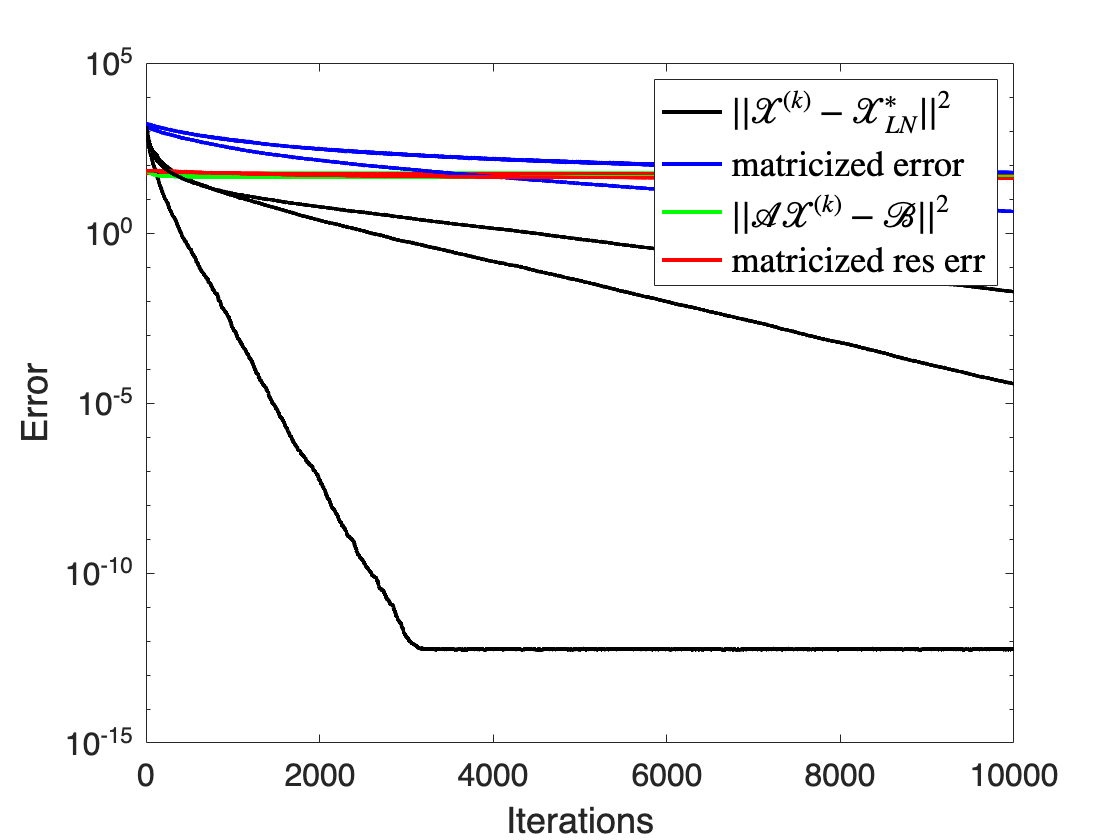

%plot errors vs iterations
figure(4);
semilogy(0:num_its,errs,'g-',0:num_its,mat_err,'r-',0:num_its,res_errs,'k-',0:num_its,mat_res_err,'b-','LineWidth',2)
hold on
set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{X}^{(k)} - \mathcal{X}_{LN}^*||^2$','matricized error','$||\mathcal{A}\mathcal{X}^{(k)} - \mathcal{B}||^2$','matricized res err','Interpreter','latex','FontSize',18)
saveas(gca,'fig1_1.png')
hold off

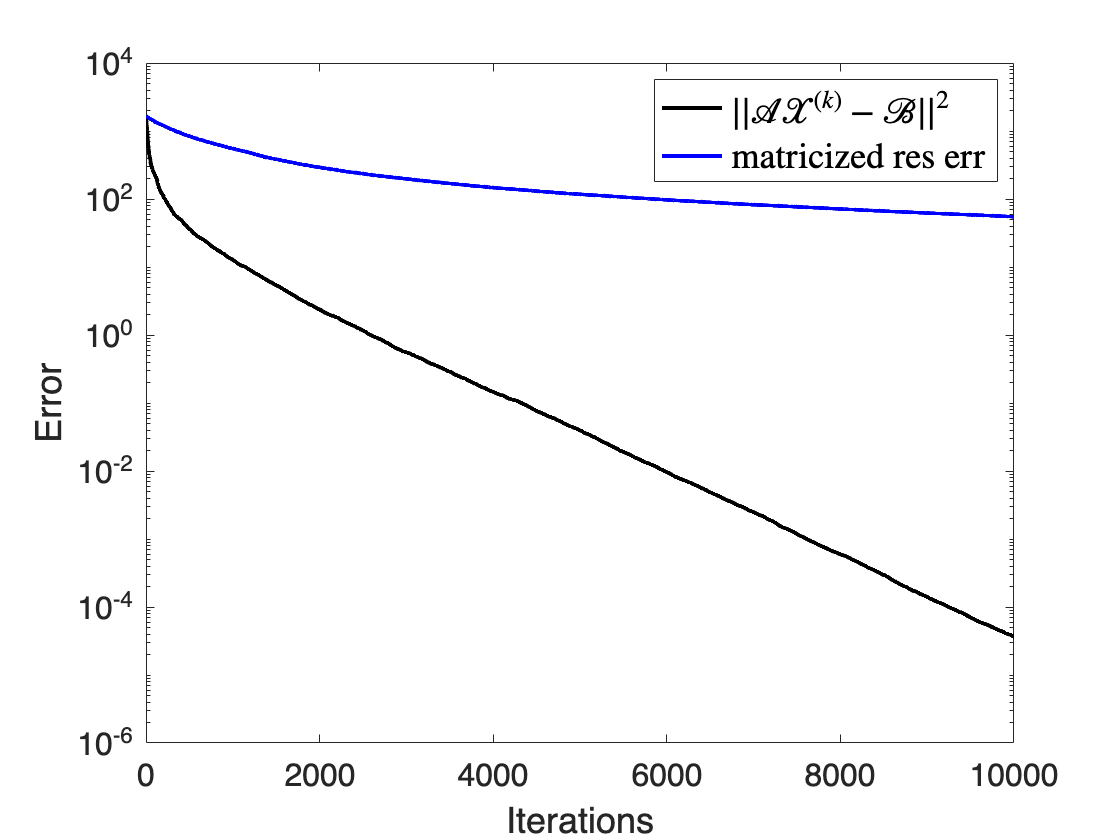

%plot errors vs iterations
figure(5);
semilogy(0:num_its,res_errs,'k-',0:num_its,mat_res_err,'b-','LineWidth',2)
hold on
set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{A}\mathcal{X}^{(k)} - \mathcal{B}||^2$','matricized res err','Interpreter','latex','FontSize',18)

saveas(gca,'fig1_2.png')
hold off

l = 20;
p = 10;
n = 30;
m = 10;

%generate tensors
A = randn(m,l,n);
X_true = randn(l,p,n);

%generate consistent measurements
B = tprod(A,X_true);

%generate equivalent matrix system
[matA,matB,matX_true] = matricization(A,B,X_true);

Now, let's test the implementation of tRGS.

%run some iterations of tRGS
num_its = 10000;
X_ln = tprod(tpinv(A),B);
errs = tRGS_err(A,B,zeros(l,p,n),num_its,X_ln)

errs =    55.4706   58.3590   60.5416   62.6609   63.4283   63.8141   64.1973   64.2093   64.1015   64.3306   63.9673   63.9349   63.6269   63.6472   63.5925   63.3591   63.0061   63.0512   63.4509   63.0619   63.2561   63.0326   62.2700   62.2700   62.6591   62.7858   63.0020   62.5749   62.8421   63.0286   62.7737   62.8453   62.3365   62.3365   62.1658   62.0910   62.0106   62.3908   62.4566   62.5310   62.0885   61.6714   61.6700   61.6502   61.4271   61.4637   61.4397   61.5164   61.4771   61.5228



res_errs = tRGS_res_err(A,B,zeros(l,p,n),num_its,X_true) 

res_errs = 1.0e+03 *

    1.3908    1.2637    1.1825    1.0979    1.0121    0.9950    0.9332    0.8742    0.8684    0.8545    0.8082    0.8082    0.7947    0.7454    0.7143    0.6548    0.6129    0.5968    0.5542    0.5160    0.4890    0.4746    0.4593    0.4288    0.4157    0.4097    0.3759    0.3618    0.3497    0.3437    0.3430    0.3225    0.3126    0.3032    0.3024    0.2912    0.2882    0.2858    0.2668    0.2564    0.2423    0.2379    0.2298    0.2193    0.2074    0.1957    0.1912    0.1867    0.1813    0.1775


matX_ln = tprod(tpinv(matA),matB);
mat_err = tRGS_err(matA,matB,zeros(n*l,p,1),num_its, matX_ln);
mat_res_err = tRGS_res_err(matA,matB,zeros(n*l,p,1),num_its, matX_true);


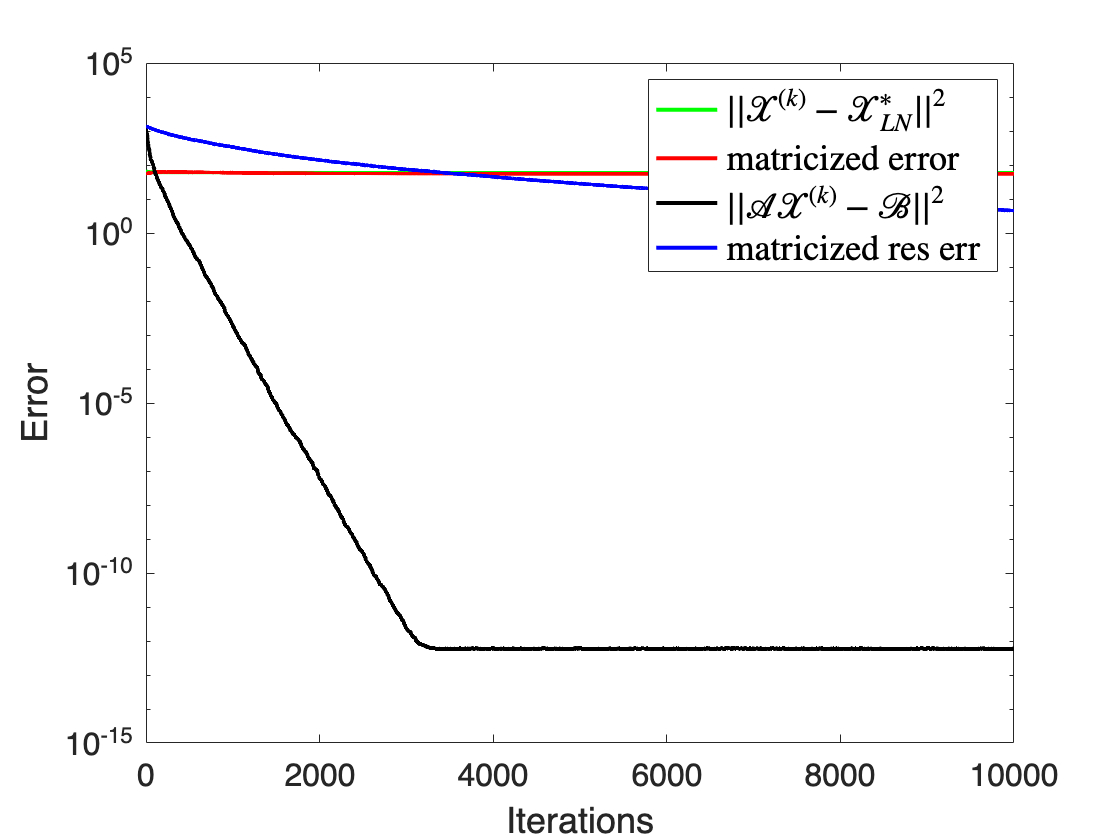

%plot errors vs iterations
figure(6);
semilogy(0:num_its,errs,'g-',0:num_its,mat_err,'r-',0:num_its,res_errs,'k-',0:num_its,mat_res_err,'b-','LineWidth',2)
hold on
set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{X}^{(k)} - \mathcal{X}_{LN}^*||^2$','matricized error','$||\mathcal{A}\mathcal{X}^{(k)} - \mathcal{B}||^2$','matricized res err','Interpreter','latex','FontSize',18)

hold off

%plot errors vs iterations
figure(7);
semilogy(0:num_its,res_errs,'k-',0:num_its,mat_res_err,'b-','LineWidth',2)
hold on
set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{A}\mathcal{X}^{(k)} - \mathcal{B}||^2$','matricized res err','Interpreter','latex','FontSize',18)
hold off

